# Prácticas de Matlab

# Resolución de EDO con métodos implícitos

# Hoja 4

**Nombre:**

**Apellido:**

**DNI:**

## 1. Implementación de métodos implícitos

## Práctica 1 (Implementación del método de Euler implícito)

Escribid en el apéndice A1 4 funciones que implementen el método de Euler (implícito) 


$$      \left\{\begin{array}{l}               y_{i+1}=y_i + h f(t_{i+1},y_{i+1}) 
\quad i=0,\ldots ,N-1          \\               y_0 \approx a        \end{array}$$


para el PVI (problema de valor inicial para sistemas de EDOs) en varias maneras Existen las siguientes maneras de implementar dicho método, dependiendo de 

- qué tipo de iteración usas para resolver la relación implícita 

- cómo eliges el dato inicial para esa iteración.

En cualquier caso, tenéis que implementar la iteración usando un

- **while** y una tolerancia dada.

- un numero máximo de iteraciones para evitar un bucle infinito.

La iteración puede ser bien esto, bien esto

- Una iteración simple.

- Una iteración tipo Newton

La elección del punto inicial para la iteración puede ser:

- el valor del paso anterior. 

- el valor calculado por un método explícito, como por ejemplo Euler explícito. (Conocido como  **predictor-corrector**)

Por lo tanto, son posibles las siguientes implementaciones:

- mieulerimpfix: Iteración simple+dato inicial el valor del paso anterior, y que responda a la sintaxis

- mieulernwt: Iteración tipo Newton+dato inicial el valor del paso anterior y que responda a la sintaxis

- meulerfixpc: Iteración simple+dato inicial por el método de Euler y que responda a la sintaxis

- mieulernwtpc: Iteración tipo Newton+dato inicial por el método de Euler y que responda a la sintaxis

## Práctica 2 (El método del trapecio)

Repetid el ejercicio anterior implementando el método del trapecio

## Práctica 3 (Ecuación no rígida con Euler implícito)

Considerad el siguiente sistema 


$$  y^{\prime}(t)  =  Ay(t) + B(t) \quad t\in [0,10]$$



$$    A=  \left(      \begin{array}{cc}        -2 & 1\\        1 & -2      
\end{array}    \right)    \qquad      B(t) =          \left(            \begin{array}{cc}              
2\sin(t)\\              2(\cos(t)-\sin(t)            \end{array}          \right)$$



$$          y(0)=          \left(             \begin{array}{c}              
2\\              3            \end{array}          \right)$$


La solución exacta es:


$$  y=2e^{-t}   \left(     \begin{array}{c}      1\\      1    \end{array}  
\right)  +  \left(     \begin{array}{c}      \sin(t)\\      \cos(t)    \end{array}  
\right)$$


Haced un diagrama de eficiencia (solo para $N$) en la misma manera como en la práctica anterior

- comparando los métodos de **mieulerimpnwt**, **mieulerimpfix** 

**Solución**

disp('H4: codigo de ')

- comparando los métodos de **mieulerimpnwt**, **mieulerimpfixpc**

**Solución**

disp('H4: codigo de ')

- comparando los métodos de **mieulerimpnwtpc**, **mieulerimpnwtpc**

**Solución**

disp('H4: codigo de ')

- calcula la pendiente de las rectas

**Solución**

disp('H4: codigo de ')

## Práctica 4 (Ecuación no rígida con el trapecio)

Repetid la práctica 3 pero con el método del trapecio de la práctica 2.

**Solución**

## Práctica 5 (Ecuación rígida con Euler implícito)

Considerad el siguiente sistema 


$$  y^{\prime}(t)  =  Ay(t) + B(t) \quad t\in [0,10]$$



$$  \left(   A=  \begin{array}{cc}    -2 & 1\\    998 & -999   \end{array}   
\right)  \quad  B(t)=\left(   \begin{array}{c}    2\sin(t)\\    999(\cos(t)-\sin(t))  
\end{array} \right)$$



$$          y(0)=          \left(             \begin{array}{c}              
2\\              3            \end{array}          \right)$$


La solución exacta es:


$$  y=2e^{-t}   \left(     \begin{array}{c}      1\\      1    \end{array}  
\right)  +  \left(     \begin{array}{c}      \sin(t)\\      \cos(t)    \end{array}  
\right)$$


Haced un diagrama de eficiencia (solo para $N$) en la misma manera como en la práctica anterior

- comparando los métodos de **mieulerimpnwt**, **mieulerimpfix** 

**Solución**

disp('H4: codigo de ')

- comparando los métodos de **mieulerimpnwt**, **mieulerimpfixpc**

**Solución**

disp('H4: codigo de ')

- comparando los métodos de **mieulerimpnwtpc**, **mieulerimpnwtpc**

**Solución**

disp('H4: codigo de ')

- calcula la pendiente de las rectas

**Solución**

## Práctica 6 (Ecuación rígida con el trapecio)

Repetid la práctica 5 pero con el método del trapecio de la práctica 2.

**Solución**

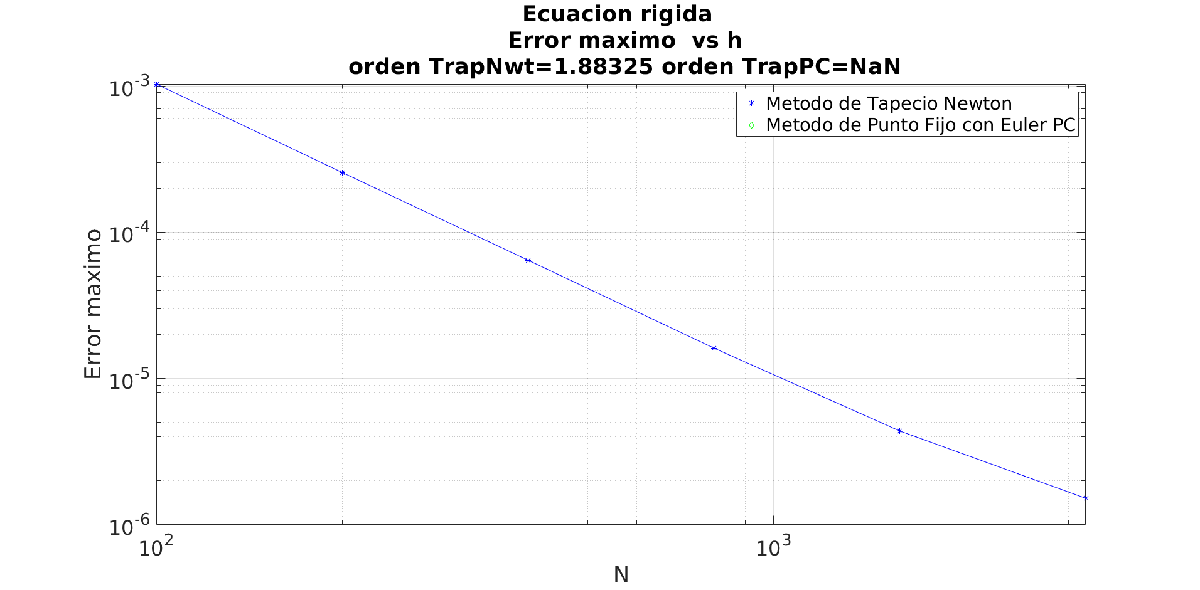

## Apéndice: la implementación de las prácticas 1+2

function [teuler,yeuler,ev]=mieulerimpfix(f,intv,y0,N,TOL,nmax) 
disp('H4: file: mieulerimpfix Alumno')
end
function [teuler,yeuler,ev]=mieulerimpfixpc(f,intv,y0,N,TOL,nmax) 
disp('H4: file: mieulerimpfixpc Alumno')
end
function [tvals, yvals,ev,loopcount]=mieulerimpnwt(f,jfunc,intv,y0,N,TOL,nmax)
disp('H4: file: mieulerimpnwt Alumno')
end
function [tvals, yvals,ev]=mieulerimpnwtpc(f,jfunc,intv,y0,N,TOL,nmax)
disp('H4: file: mieulerimpnwtpc Alumno')
end
function [ttrap,ytrap,ev,loopcount]=mitrapfix(f,intv,y0,N,TOL,nmax) 
disp('H4: file: mitrapfix Alumno')
end
function [ttrap,ytrap,ev,loopcount]=mitrapfixpc(f,intv,y0,N,TOL,nmax) 
disp('H4: file: mitrapfixpc Alumno')
end
function [ttrap,ytrap,ev,loopcount]=mitrapnwt(f,jfunc,intv,y0,N,TOL,nmax)
disp('H4: file: mitrapnwt Alumno')             
end
function [ttrap,ytrap,ev,loopcount]=mitrapnwtpc(f,jfunc,intv,y0,N,TOL,nmax)
disp('H4: file: mitrapnwtpc Alumno')
end

function [N_vect,Ev_vect,error_vect]=fcomparerrorimpnwt(met,func,jacfunc,intv,y0,N,yexact,M,TOL,nmax);
disp('H4: file: fcomparerrorimpnwt Alumno')
end 

function [N_vect,Ev_vect,error_vect]=fcomparerrorimpfix(met,func,intv,y0,N,yexact,M,TOL,nmax);
disp('H4: file: fcomparerrorimpfix Alumno')
end

function [p,q]=fcalcorden(N_vect,error_vect) 
disp('H4: file: fcalcorden Alumno')
end